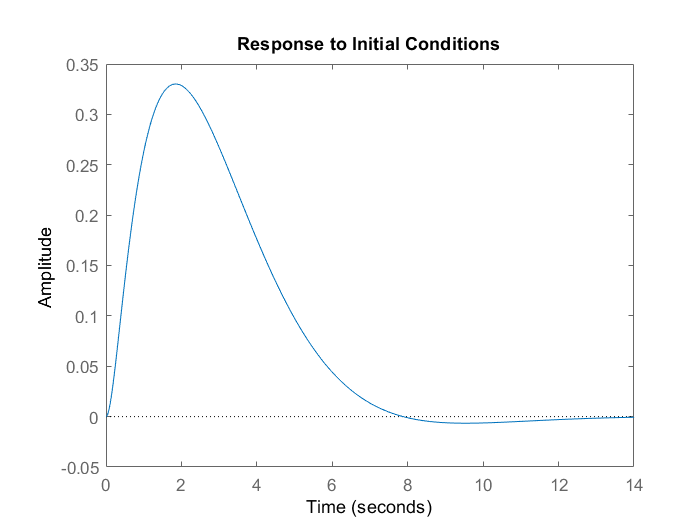

% System response using LQR method

A = [0 1 0 0;20.601 0 0 0;0 0 0 1;-0.4905 0 0 0];
B = [0;-1;0;0.5];
C = [0 0 1 0];
D = [0];
Q=[100 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1];
R=[1];
k=lqr(A,B,Q,R);
sys=ss(A-B*k,B,C,D);
%System response with initial condition
x0=[0.1;0;0;0];
t=0:0.1:10;
%step(initial(sys,x0,t))
initial(sys,x0)

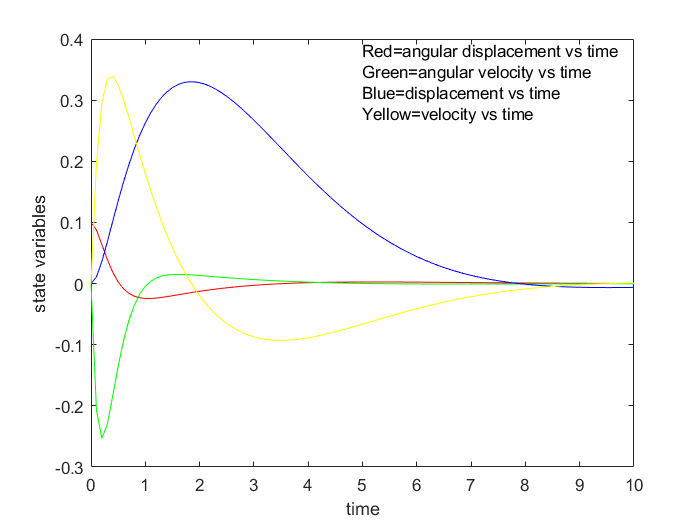

[y,t,x] = initial(sys,x0,t);
x1 = [1 0 0 0 ]*x';
x2 = [0 1 0 0 ]*x';
x3 = [0 0 1 0 ]*x';
x4 = [0 0 0 1 ]*x';
%Required curves
plot(t,x1,'r')
hold on
plot(t,x2,'g')
hold on
plot(t,x3,'b')
hold on
plot(t,x4,'y')
txt={'Red=angular displacement vs time','Green=angular velocity vs time','Blue=displacement vs time','Yellow=velocity vs time'};
text(5,.33,txt)
xlabel('time')
ylabel('state variables')
hold off